% Load the XDF library (Ensure the XDF library is added to your MATLAB path)
addpath('C:\Users\Brandon\Documents\MATLAB\xdf-Matlab-master'); % Replace with the path to the XDF MATLAB library

% Specify the path to your XDF file
xdf_file_path = 'C:\Users\Brandon\Documents\2025 Fall\EEG_Analysis\sub-P00NmVisual2_ses-S001_task-Default_run-001_eeg.xdf'; % Replace with your .xdf file's path

% Load the XDF file
disp('Loading XDF file...');

Loading XDF file...


[streams, fileheader] = load_xdf(xdf_file_path);

% Display all streams
disp('Available Streams:');

Available Streams:


for i = 1:length(streams)
    fprintf('Stream #%d\n', i);
    fprintf('  Name: %s\n', streams{i}.info.name);
    fprintf('  Type: %s\n', streams{i}.info.type);
    fprintf('  Channel Count: %s\n', streams{i}.info.channel_count);
    fprintf('  Nominal Sampling Rate: %s\n', streams{i}.info.nominal_srate);
    fprintf('  Time Series Length: %d samples\n', size(streams{i}.time_series, 1));
    fprintf('  Data Type: %s\n', streams{i}.info.type);
    fprintf('  Unique ID: %s\n\n', streams{i}.info.source_id);
end

Stream #1


  Name: MarkerStream


  Type: Markers


  Channel Count: 2


  Nominal Sampling Rate: 0.000000000000000


  Time Series Length: 2 samples


  Data Type: Markers


  Unique ID: marker_stream_id



Stream #2


  Name: eegoSports 000170


  Type: EEG


  Channel Count: 39


  Nominal Sampling Rate: 512.0000000000000


  Time Series Length: 39 samples


  Data Type: EEG


  Unique ID: eegoSports_000170




disp('Stream display complete.');

Stream display complete.



eeg_stream = streams{1,2};
eeg_data = eeg_stream.time_series;
disp(size(eeg_data))

          39      460459



num_channels = size(eeg_data, 1);
num_samples = size(eeg_data, 2);
channel_labels = cell(1, numel(num_channels));

for s=1:num_channels
    channel_labels{s} = streams{1, 2}.info.desc.channels.channel{1, s}.label
end

channel_labels = 1×1 cell array
    {'AF3'}


channel_labels = 1×2 cell array
    {'AF3'}    {'AF4'}


channel_labels = 1×3 cell array
    {'AF3'}    {'AF4'}    {'F3'}


channel_labels = 1×4 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}


channel_labels = 1×5 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}


channel_labels = 1×6 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}


channel_labels = 1×7 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}


channel_labels = 1×8 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}


channel_labels = 1×9 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}


channel_labels = 1×10 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}


channel_labels = 1×11 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}


channel_labels = 1×12 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}


channel_labels = 1×13 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}


channel_labels = 1×14 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}


channel_labels = 1×15 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}


channel_labels = 1×16 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}


channel_labels = 1×17 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}


channel_labels = 1×18 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}


channel_labels = 1×19 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}


channel_labels = 1×20 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}


channel_labels = 1×21 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}


channel_labels = 1×22 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}


channel_labels = 1×23 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}


channel_labels = 1×24 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}


channel_labels = 1×25 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}


channel_labels = 1×26 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}


channel_labels = 1×27 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}


channel_labels = 1×28 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}


channel_labels = 1×29 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}


channel_labels = 1×30 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}


channel_labels = 1×31 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}


channel_labels = 1×32 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}    {'O2'}


channel_labels = 1×33 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}    {'O2'}    {'AUX1'}


channel_labels = 1×34 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}    {'O2'}    {'AUX1'}    {'AUX2'}


channel_labels = 1×35 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}


channel_labels = 1×36 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}    {'AUX7'}


channel_labels = 1×37 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}    {'AUX7'}    {'AUX8'}


channel_labels = 1×38 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}    {'AUX7'}    {'AUX8'}    {'AUX9'}


channel_labels = 1×39 cell array
    {'AF3'}    {'AF4'}    {'F3'}    {'F1'}    {'FZ'}    {'F2'}    {'F4'}    {'FC3'}    {'FC1'}    {'FCZ'}    {'FC2'}    {'FC4'}    {'C3'}    {'C1'}    {'CZ'}    {'C2'}    {'C4'}    {'CP3'}    {'CP1'}    {'CPZ'}    {'CP2'}    {'CP4'}    {'P3'}    {'P1'}    {'PZ'}    {'P2'}    {'P4'}    {'PO3'}    {'POZ'}    {'PO4'}    {'O1'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}    {'AUX7'}    {'AUX8'}    {'AUX9'}    {'TRIGGER'}



% Extract time series and timestamps
timestamps = eeg_stream.time_stamps; % Corresponding timestamps
marker_times = streams{1,1}.time_stamps;
% Initialize an index array
n_marks = zeros(1, length(marker_times));  % Preallocate for efficiency

% Find the indices of the closest matching timestamps for each marker time
for i = 1:length(marker_times)
    [~, n_marks(i)] = min(abs(timestamps - marker_times(i)));  % Find the closest index
end
%{
% Display the indices
disp('Indices of samples where markers occurred:');
disp(n_marks);

% Plot time series for each EEG channel
n = 1:num_samples;
figure;
hold on;  % Allow multiple lines to be plotted on the same figure
for channel = 1:num_channels
    plot(n, eeg_data(channel, :), 'DisplayName', channel_labels{channel});
end

% Add vertical red lines for each marker index
for i = 1:length(marker_times)
    xline(n(i), 'r', 'LineWidth', 1.5);
end

% Add labels, title, and legend
xlabel('Sample Number (n)');
ylabel('Amplitude');
title('EEG Time Series Data for All Channels (X-Axis: Sample Number)');
legend('Location', 'eastoutside');  % Move the legend outside the plot
grid on;
hold off;  % Release the hold on the plo
% 
%}

## DO NOT ANALYZE 5000 MARKERS

## plot cz and fz

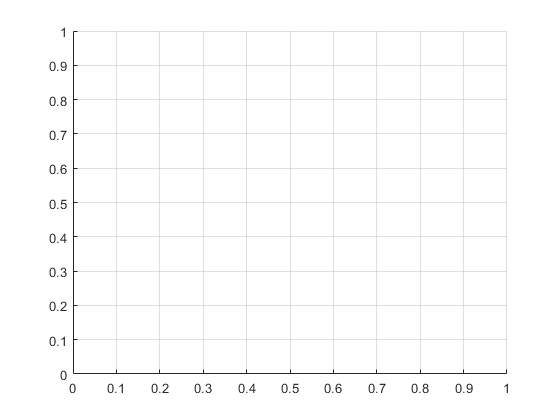


% Filter data (band-pass filtering)
 % Sampling rate (example: 1000 Hz)
 low_cutoff = 1;
 high_cutoff = 30;
 fs = 512;
 [b, a] = butter(2, [low_cutoff, high_cutoff] / (fs / 2));  % 2nd-order Butterworth filter
 filtered_data = filtfilt(b, a, eeg_data);

% % Epoching (extract -200 ms to +800 ms windows)
% epoch_start = -200; % in ms
% epoch_end = 800; % in ms
% baseline_start = -200; % in ms
% baseline_end = 0; % in ms
%
% % (Assume trigger_times contains stimulus onset times in samples)
% epochs = [];
% for i = 1:length(trigger_times)
%     epoch = eeg_data(:, trigger_times(i) + epoch_start:trigger_times(i) + epoch_end);
%     baseline = mean(epoch(:, baseline_start:baseline_end), 2); % Baseline correction
%     epochs = cat(3, epochs, epoch - baseline); % Collect all epochs
% end
%
% % Average ERP for each channel
% erp = mean(epochs, 3);
%
% % Plot ERP for a single channel
% figure;
% plot(epoch_start:epoch_end, erp(1, :)); % Example: Plot ERP for channel 1
% xlabel('Time (ms)');
% ylabel('Amplitude (\muV)');
% title('ERP for Channel 1');
% grid on;
combined_export.filtered_data = filtered_data';
combined_export.triggers = streams{1,1}.time_series;
combined_export.trigger_index = n_marks;

save('preprocessed.mat', 'combined_export');

%figure;
%plot(streams{1,1}.time_series(2,:), streams{1,1}.time_series(1,:));

grid on;